% load('amsr_n3125_Arctic_m03_y2025-v5.4.mat');
month = month_ts(1);
day = 12;
year = year_ts(1);

lat = double(lat);
lon = double(lon);
seaice = double(squeeze(seaice_ts(1,:,:)));

% If longitude is 0–360°, convert to –180–180° range
lon(lon > 180) = lon(lon > 180) - 360;

%% Define the region of interest (ROI), i.e., Scoresby Sund
lat_min = 69.7; 
lat_max = 71;
lon_min = -25; 
lon_max = -20;

% Create a mask for the region
mask = lat >= lat_min & lat <= lat_max & lon >= lon_min & lon <= lon_max;

% Find bounding box indices
[row, col] = find(mask);
rmin = min(row); rmax = max(row);
cmin = min(col); cmax = max(col);

% Subset data to region
lat_roi = lat(rmin:rmax, cmin:cmax);
lon_roi = lon(rmin:rmax, cmin:cmax);
sic_roi = seaice(rmin:rmax, cmin:cmax);

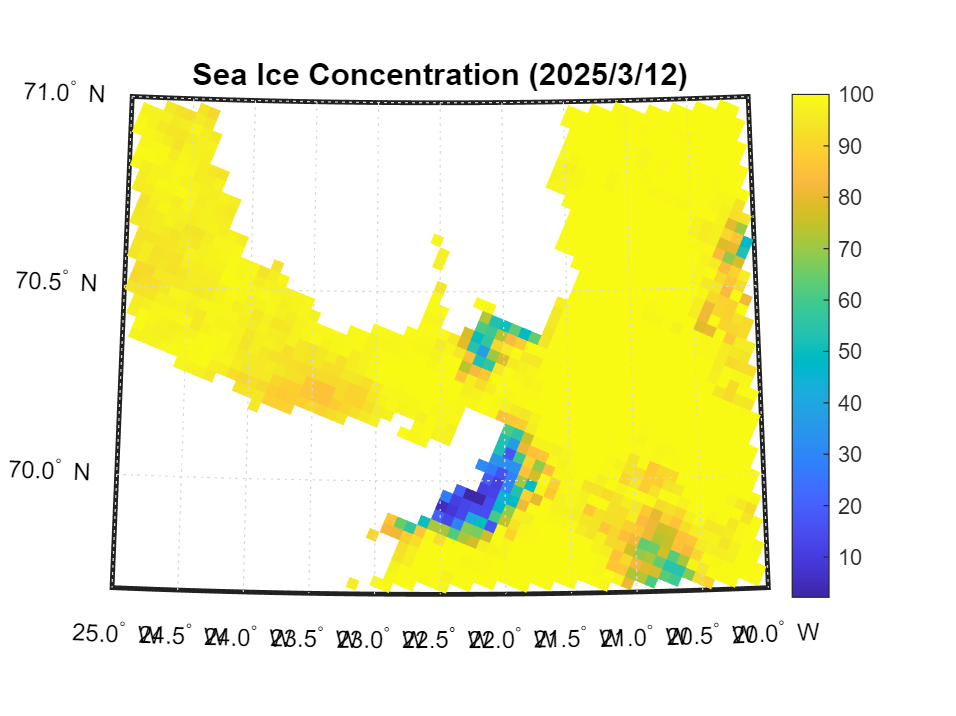

R = georefcells([lat_min,lat_max], [lon_min,lon_max], size(sic_roi));

%% Create map
figure('Color','w');
worldmap(sic_roi, R);

%% Overlay sea ice concentration
pcolorm(lat_roi, lon_roi, sic_roi);
colormap("parula");
% Adjust color limits to 0–50% to show more details
%clim([0 50]);
colorbar;
title_string = sprintf('Sea Ice Concentration (%u/%u/%u)', year, month, day);
title(title_string, 'FontSize', 13);